# kgme - single fish

## load data structure

IN LAB

load("/Volumes/Elements/rkg.mat");
%load("/Users/eric/Documents/MATLAB/rkg.mat");
%addpath('/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/');

## save data structure

IN LAB

 save("/Users/eric/Documents/MATLAB/rkg.mat", "rkg", '-v7.3');
% save("/Volumes/Elements/rkg.mat", 'rkg', '-v7.3');
save("/Volumes/My Book/Gallman/rkg.mat", 'rkg', '-v7.3');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/rkgbackup.mat", "rkg");
save("/Volumes/Elements/rkg.mat", 'rkg');

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/Elements/Gallman/2424LD/Cheshire24-Dec-05-2021-D/");
k = 79;

k = 1      4:4 LD        Sandwhiches-Eigen04-Jan-24-2021-B

k = 2      4:4 LD        Olaf-Eigen04-Jan-24-2021-C

k = 3      48:48 LD    Social-Eigen48-Nov-22-2020-A

k = 4      48:48 LD    Social2-Eigen48-Nov-22-2020-B

k = 5      48:48 LD     Unsocial-Eigen48-Nov-22-2020-C

k = 6      10:10 LD     Eugene - Eigen10-05-Oct-2020-A

k = 7      10:10 LD     Ralf - Eigen10-05-Oct-2020-B - Eric this is so low amp that i need help... weirdly looks ok for sumfft but not obwamp

k = 8       6:6 LD        Eugene - Eigen6-12-Oct-2020-A

k = 9       6:6 LD        Ralf-Eigen6-12-Oct-2020-B

k = 10     24:24 LD    Ralf-Eigen24-Oct-30-2020-B

k = 11     24:24 LD    Sandwiches-Eigen24-Oct-20-2020-C (only really one full subjective day) - maybe add to hourdays

k = 12     12:12 LD    Large small - LigSm-14-Dece-2020-A

k = 13     12:12 LD    Milo - Milo20Dec20200-B    *need to fix feeding times, currently empty (originally set to combine after DarkLarge)

k = 14     12:12 LD    Green12-14Dec2020-C

k = 15      %changing from kg to 12:12 LD    DarkLarge -DkLrg12-12Dec2020-B    dying fish

k = 16     12:12 LD     Milo - Eigen12-Jan-12-2021-B

k = 17     12:12 LD     Potts - Eigen12-Jan-2021-C (second fish frequency)

k = 18      5:5 LD        Ralf -Eigen5-Nov-8-2020-B

k = 19      5:5 LD        Ralf -Eigen5-Nov-8-2020-B -different poweridx than 18

k = 20      5:5 LD        Sandwiches-Eigen5-Nov-8-2020-C

k = 21     12:12 LD      Pepper - Eigen12-Jan-2021-C (first fish frequency)

k = 22    

k = 23     12:12 LD      Eigen12-Jan-12-2021-A

k = 24      5:5 LD         Sandwiches-Eigen5-Nov-8-2020-C - different poweridx than k = 20

k = 25      8:8 LD         Polka08-March-16-2021-A

k = 26      8:8 LD         Dott8-March-16-2021-B

k = 27      8:8 LD         Weeny8-March-23-2021-C

k = 28      13:13 LD     Weeny13-March-31-2021-C

k = 29      13:13 LD     Polka13-March-31-2021-A

k = 30      13:13 LD     Dott13-March-31-2021-B

k = 31       %repeat of k = 28 in kg...

k = 32        %kg data not worth it

k = 33        6:6 LD    Dott06-April-17-2021-B

k = 34        6:6 LD    Weeny6-April-17-2021-C

k = 35        8:8 LD    Eugene: Eigen-28-Sept-2020-A

k = 36        8:8 LD    Ralf: Eigen28Sept2020-B

k = 37        20:20 LD    Bikini20-May-07-2021-A     - may need to re-normalize. large amplitude range in data

k = 38        20:20 LD    Dott20-May-07-2021-B

k = 39        20:20 LD    Itsy20-May-07-2021-C    - huge amplitude increase at end...

k = 40        20:20 LD    Dott20-May-02-2021-B

k = 41        16:16 LD    Dott16-May-2021-B

k = 42        16:16 LD    Bikini16-May-18-2021-A     

k = 43         16:16 LD    Itsy16-May-18-2021-C    

k = 44        48:48 LD    Bikini48-May-21-2021-A   

k = 45        48:48 LD    Dott48-May-21-2021-B - only channel 2 data is good

k = 46        48:48 LD    Yellow48-May-24-2021-C    only channel 1 data is good for entire timcont

k = 47        12:12  LD   Bikini12-June-29-2021-A     second half temp modulation (maybe divide into two)

k = 48        12:12 LD temp Bikini12-July-13-2021-A - all over the place data

k = 49        48L48 LDtemp    Bikini48-July-19-2021-A - funky data

k = 50        XXtemp - mostly dark BikiniXX-July-30-2021-A    ONLY USE CH1

k = 51        XXtemp - mostly dark MaryXX-Aug-1-2021-C    ONLY USE CH1

k = 52        XXtemp  -mostly dark    BikiniXX-Aug-10-2021-A    Ch1 still far superior

k = 53        XXtemp -mostly dark    BaltoXX-Aug-10-2021-C  ONLY USE CH1

k = 54        4:4 LD    Cheshire04-Aug-21-2021-A    Ch1 is better

k = 55        4:4 LD    Balto04-Aug-31-2021-C    Ch1 better

k = 56        24:24 LD    Cheshire24-Sept-3-2021-A     USE CH1

k = 57        24:24 LD    Balto24-Sept-3-2021-C    1 st half Needs to be multiplied by gain step... saving for later

k = 58        5:5 LD    Cheshire05-Sept-13-2021-A        USE CH1

k = 59        5:5 LD    Balto05-Sept-13-2021-C        USE CH1 (heavily Removed to control for weird amplification effect)

k = 60        10:10    Cheshire10-Sept-24-2021-A    USE CH1    - needs to be adjusted aroung 100 hours - left for later

k = 61

fucking sparkle... bring laptop toms

k = 74        124 LD     Lydia124-Nov-18-2021-C    USE CH1

k = 75        124 LD     Paco124-Nov-18-2021-E    barely any dark triggers - probs don't use

k = 76        24:24 LD    Lydia24-Dec-05-2021-C    a bit multimodal

k = 77        24:24 LD     Mama24-Dec-09-2021-A    skipped redo for now - needs to be normalized in chunks? electrode bumped?

k = 78        24:24 LD    Pedro24-Dec-05-2021-E    USE CH1

## generate amplitude data

rkg(k).e = KatieAssembler('Eigen*',  23);

%rkg(k).e = KatieAssembler('Eigen*',  22); %really old data
%kg(k).e = KatieAssembler('Eigen*', 40000, 24); %Katie is bad at typing...

rkg(k).e = KatieAssemblerSig('Eigen*', 40000, 23, 300);

## initial plotter

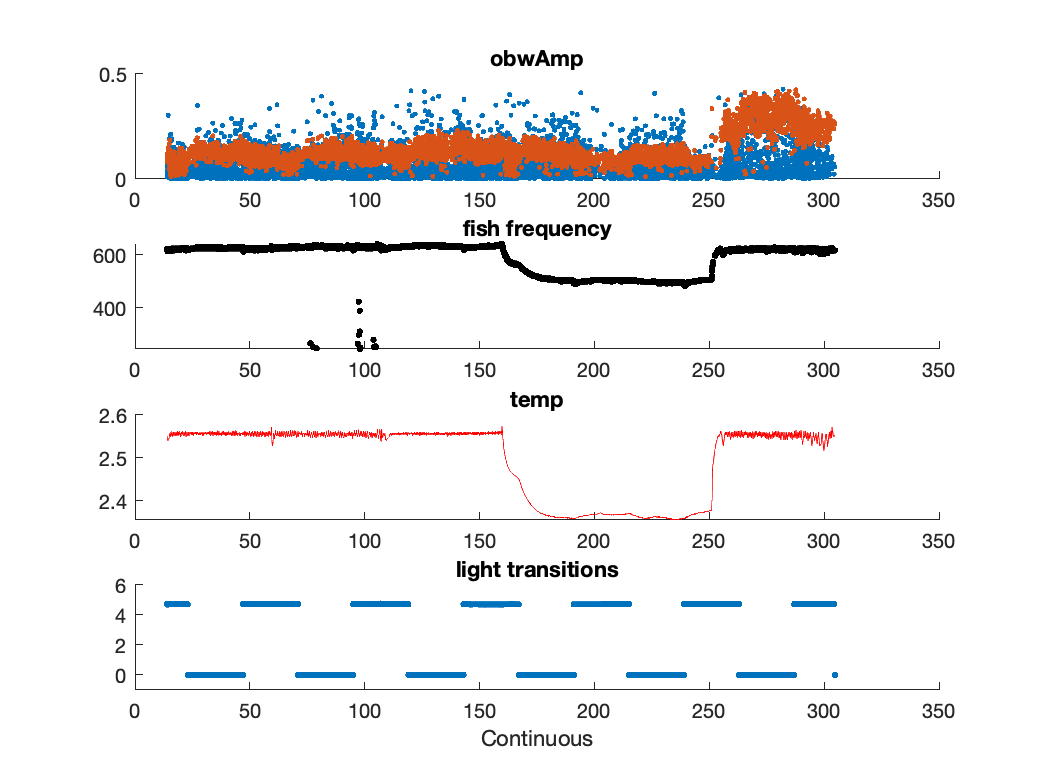

k_initialplotter(rkg(k));

#### Remove outliers

Must be redone after trimming

rkg(k).idx = KatieRemover(rkg(k).e);

## Label

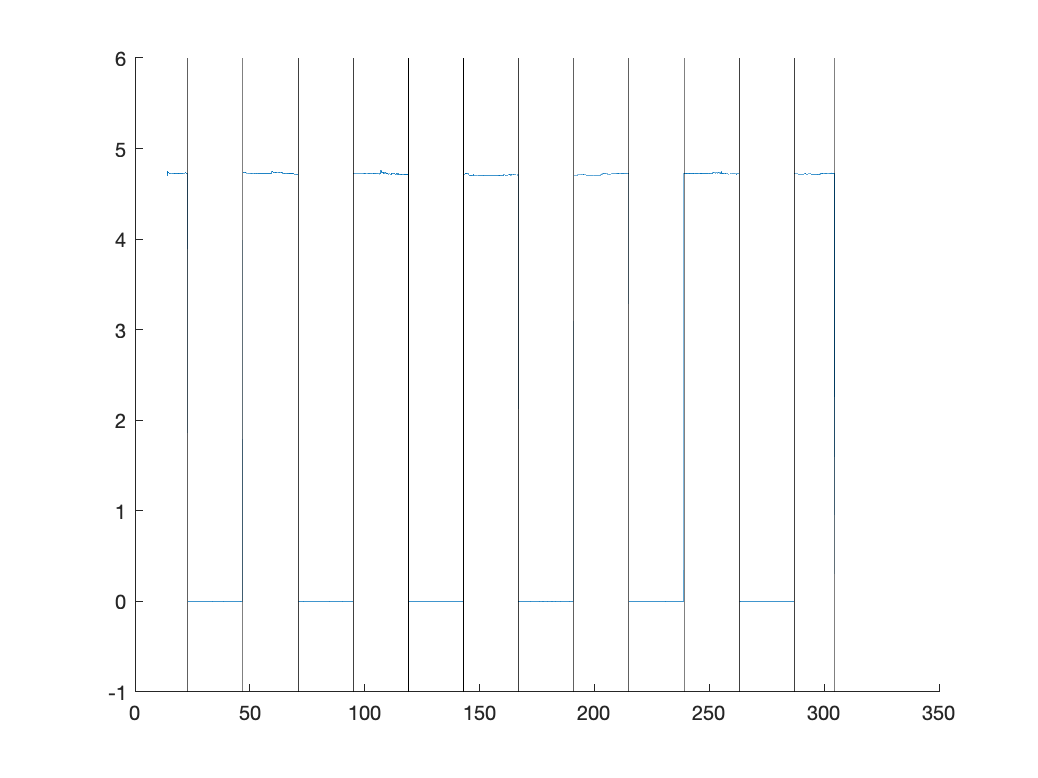

rkg(k).info = KatieTempLabeler(rkg(k).e);

## edits

#### frequency trimming

Do before outlier removal

extra step in case of instant clicking regret...

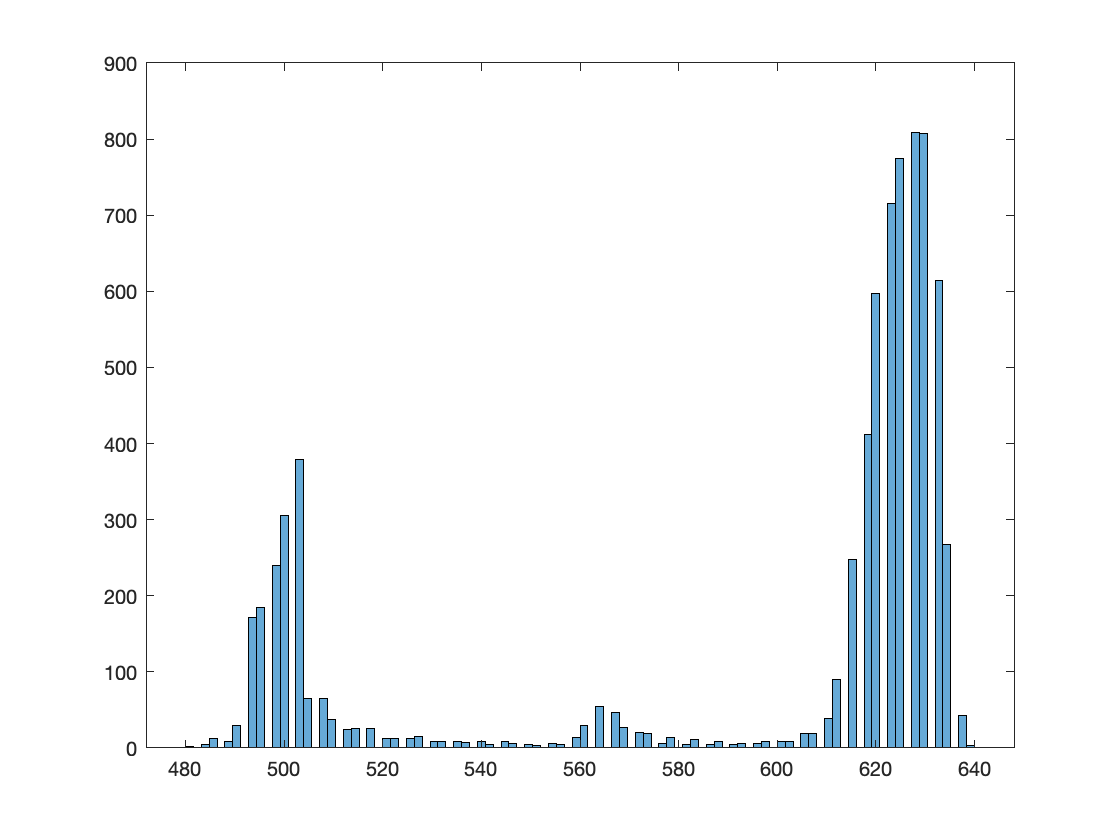

tempdata = 1×2 struct array with fields:
    s


tempdata = KatieFreakyFreqRemover(rkg(k).e)

rkg(k).e = tempdata;

#### trim data

extra step in case of instant clicking regret...

tempdata = KatieTrimmer(rkg(k).e);

if before was on purpose 

rkg(k).e = tempdata;


for channel = 1:2

    fudgeidx = find([rkg(k).e(channel).s.timcont]/3600 < 40.8);
    for kk = 1:length(fudgeidx)
    
        rkg(k).e(channel).s(fudgeidx(kk)).sumfftAmp = [rkg(k).e(channel).s(fudgeidx(kk)).sumfftAmp]*60;
        rkg(k).e(channel).s(fudgeidx(kk)).obwAmp = [rkg(k).e(channel).s(fudgeidx(kk)).obwAmp]*60;
    
    end
end